Change the temperature here according to your heart's desire

% open the googP_logits.mat file from get_logits folder

introduce_functions;



logits = dino_logits;

% logits = dino_logits ./ vecnorm(dino_logits,2,2); % if we norn get
% perfect sphere for data.
%logits = googP_logits;
% 
% logits1000 = logits(1:9999,:);
% logits_Y = logits(10000,:);

logits1000 = logits(1:9998,:);
logits_Y = logits(9999,:);

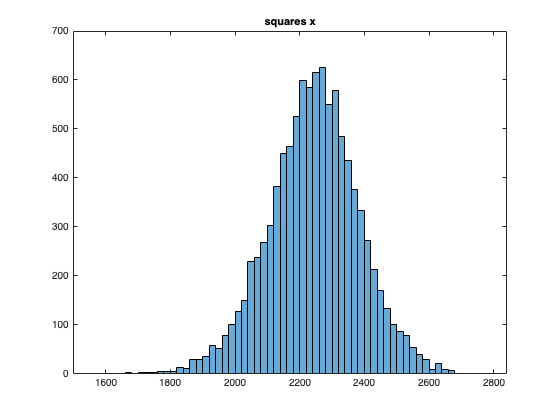

SQUARES = @(X) sum((X).^2,2);

squares_x = SQUARES(logits1000);
histogram(squares_x)
title("squares x")

squares_y = SQUARES(logits_Y)

squares_y = single
2.3775e+03

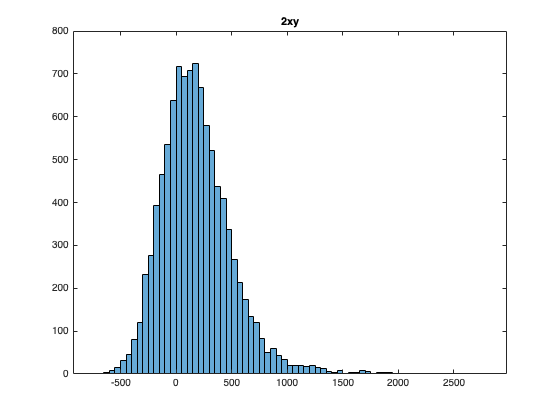

% 1:many

TWOXY = @(X,Y) 2 * sum(X .* Y,2);

%two_xy = TWOXY(logits,logits2);
% two_xy = pdist2(logits_Y, logits1000, TWOXY);
% two_xy = nonzeros(triu(two_xy,1));  non zeros of upper diagonal
% two_xy = two_xy(:);

two_xy = TWOXY(logits_Y,logits1000);

histogram(two_xy)
title("2xy")

euc = EUC(logits_Y,logits1000);

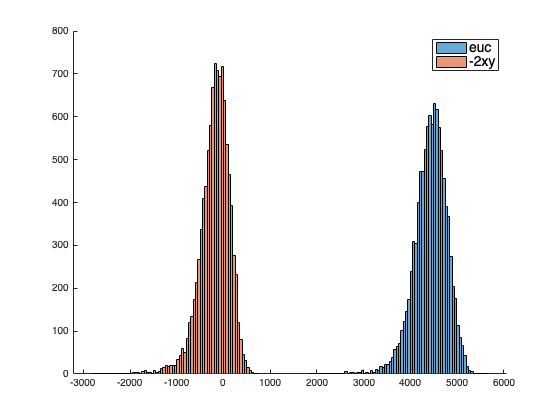

clf
hold on
histogram(euc,'DisplayName','euc')
histogram(-two_xy,'DisplayName','2xy')
%title("DinoV2: Euclidean divergence, X^2, Y^2 ","FontSize",18)
legend("euc","-2xy","FontSize",14)
hold off

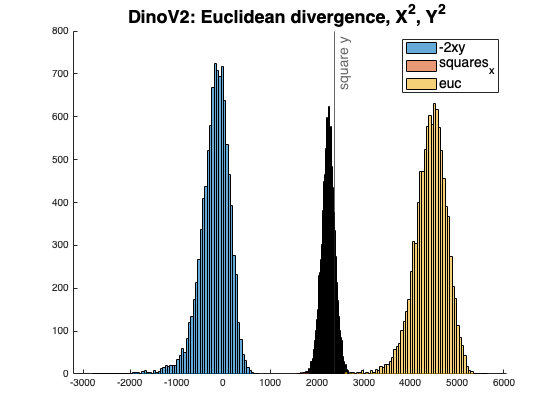


clf
hold on
histogram(-two_xy,'DisplayName','2xy')
histogram(squares_x,'DisplayName','squares x')
histogram(euc,'DisplayName','euc')
xline(squares_y,'-','square y','DisplayName','square y',"FontSize",14)
title("DinoV2: Euclidean divergence, X^2, Y^2 ","FontSize",18)
legend("-2xy","squares_x","euc","FontSize",14)
hold off

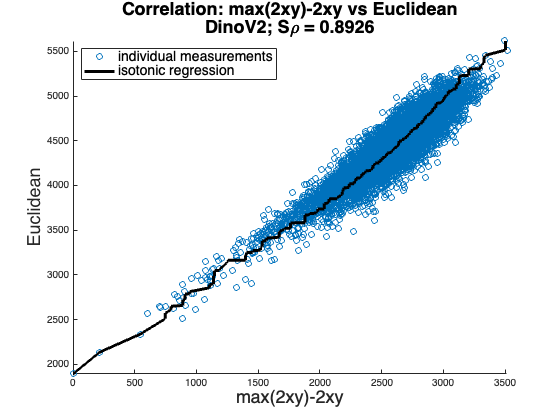

chart_title1 = "Correlation: max(2xy)-2xy vs Euclidean";
chart_title2 = "DinoV2";
chart_title = [chart_title1,chart_title2];
shepard_spear(euc,max(two_xy) - two_xy,chart_title,"max(2xy)-2xy","Euclidean");

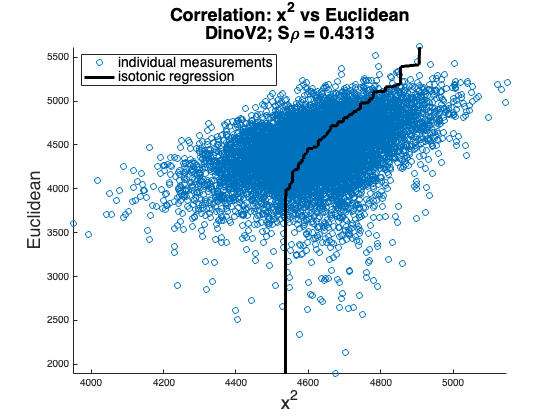

chart_title1 = "Correlation: x^2 vs Euclidean";
chart_title2 = "DinoV2";
chart_title = [chart_title1,chart_title2];
shepard_spear(euc,squares_x + squares_y,chart_title,"x^2","Euclidean");